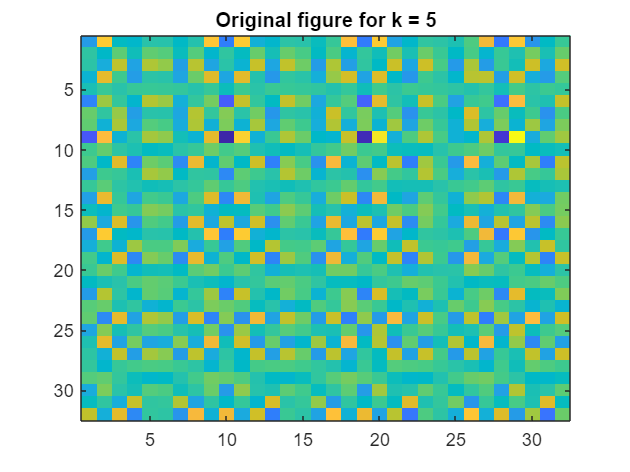

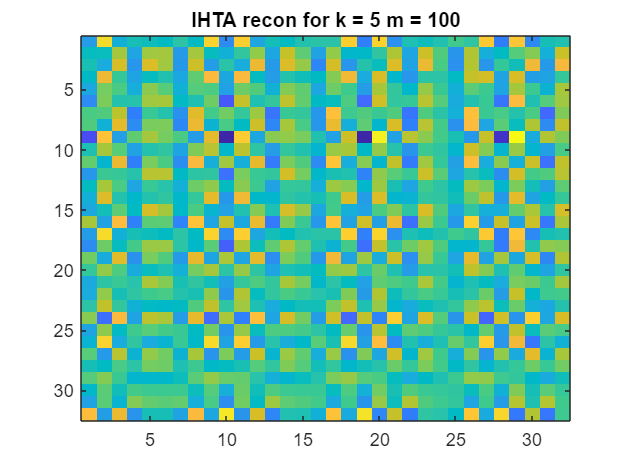

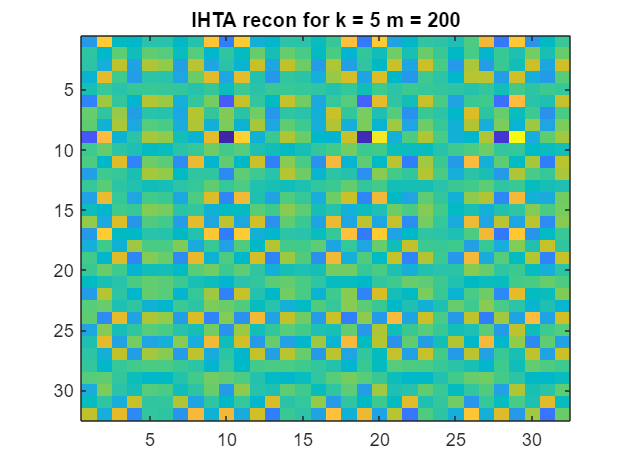

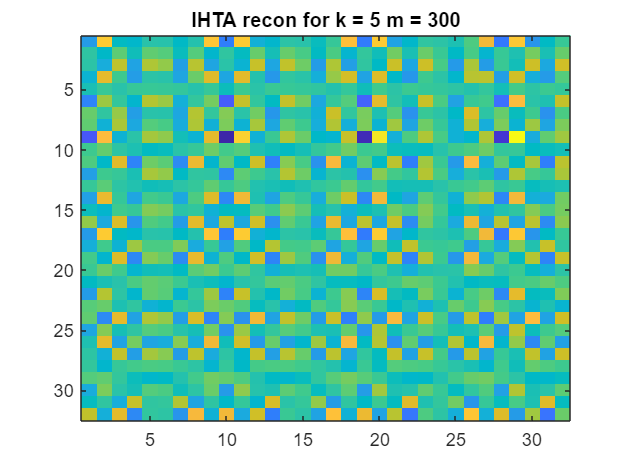

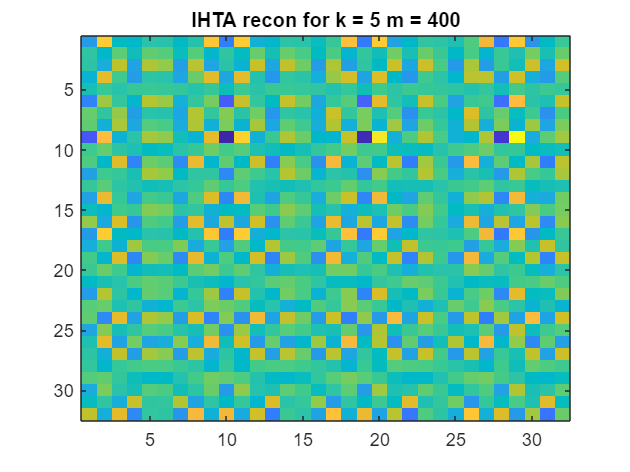

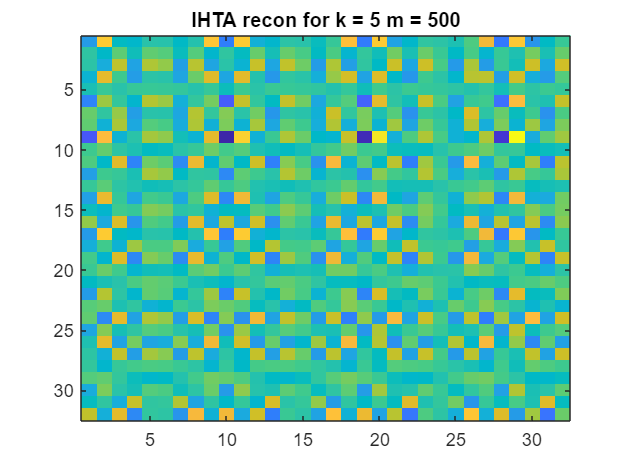

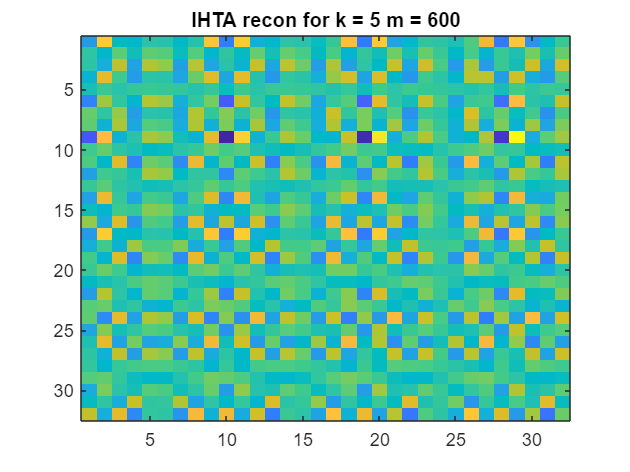

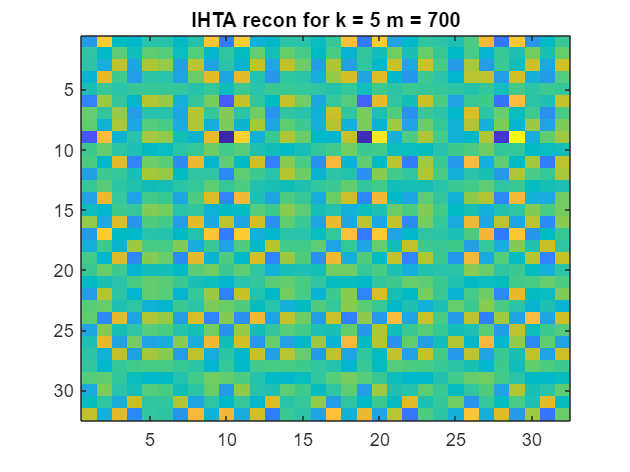

rng(10);

K = [5, 10, 20, 30, 50, 100, 150, 200];
M = [100, 200, 300, 400, 500, 600, 700, 800, 900, 1000];

C = dctmtx(32);
DCT2D = kron(C, C);

% OMP_500 = zeros(1,8);
% OMP_700 = zeros(1,8);
% for k = 1:8
%     theta = zeros(32*32, 1);
%     ind = randperm(32*32, K(k));
%     for i=1:K(k)
%         theta(ind(i), 1) = randi([-100, 100]);
%     end
% 
%     f = DCT2D*theta;
%     f_non_vec = reshape(f, [32, 32])';
%     imagesc(f_non_vec);
%     title("Original figure for k = "+K(k));
%     figure;
%     error_list = zeros(1, 10);
%     for m = 1:10
%         rad = zeros(M(m), 1024);
%         for i=1:M(m)
%             for j=1:1024
%                 rad(i,j) = (-1)^randi(2);
%             end
%         end
%         A = rad*DCT2D; 
%         A1 = A./(vecnorm(A));
%         y = A*theta;
%         theta_recov1 = OMP(A, A1, y, K(k), M(m));
%         f_recov1 = DCT2D*theta_recov1;
%         error = norm(f_recov1 - f)/norm(f);
%         error_list(m) = error;
%         %disp("OMP Error k = " +K(k)+" m = "+M(m)+ " : "+error+"\n");
%         if M(m) == 500 || M(m) == 700 || K(k) == 5 || K(k) == 50 || K(k) == 200 
%             img_recov1 = reshape(f_recov1, [32, 32])';
%             imagesc(img_recov1);
%             title("OMP recon for k = "+K(k)+" m = "+M(m));
%             figure;
%         end
%         if M(m) == 500
%             OMP_500(k) = error;
%         end
%         if M(m) == 700
%             OMP_700(k) = error;
%         end
% 
%     end
%     if K(k) == 5 || K(k) == 50 || K(k) == 200
%         plot(M, error_list);
%         title("RMSE Error vs m for k = "+K(k));
%         figure;
%     end
% end
% 
% plot(K, OMP_500);
% title("RMSE Error vs k for m = 500");
% figure;
% plot(K, OMP_700);
% title("RMSE Error vs k for m = 700");
% figure;

IHTA_500 = zeros(1, 8);
IHTA_700 = zeros(1, 8);
for k = 1:8
    theta = zeros(32*32, 1);
    ind = randperm(32*32, K(k));
    for i=1:K(k)
        theta(ind(i), 1) = randi([-100, 100]);
    end

    C = dctmtx(32);
    DCT2D = kron(C, C);
    f = DCT2D*theta;
    f_non_vec = reshape(f, [32, 32])';
    imagesc(f_non_vec);
    title("Original figure for k = "+K(k));
    figure;
    error_list = zeros(1, 10);
    for m = 1:10
        rad = zeros(M(m), 1024);
        for i=1:M(m)
            for j=1:1024
                rad(i,j) = (-1)^randi(2);
            end
        end
        A = rad*DCT2D; 
        A1 = A./(norm(A)+5);
        y = A1*theta;
        theta_recov2 = IHTA(A, A1, y, K(k), M(m));
        f_recov2 = DCT2D*theta_recov2;
        error = norm(f_recov2 - f)/norm(f);
        error_list(m) = error;
        %disp("OMP Error k = " +K(k)+" m = "+M(m)+ " : "+error+"\n");
        if M(m) == 500 || M(m) == 700 || K(k) == 5 || K(k) == 50 || K(k) == 200 
            img_recov2 = reshape(f_recov2, [32, 32])';
            imagesc(img_recov2);
            title("IHTA recon for k = "+K(k)+" m = "+M(m));
            figure;
        end
        if M(m) == 500
            IHTA_500(k) = error;
        end
        if M(m) == 700
            IHTA_700(k) = error;
        end
    end
    if K(k) == 5 || K(k) == 50 || K(k) == 200
        plot(M, error_list);
        title("RMSE Error vs m for k = "+K(k));
        figure;
    end
end

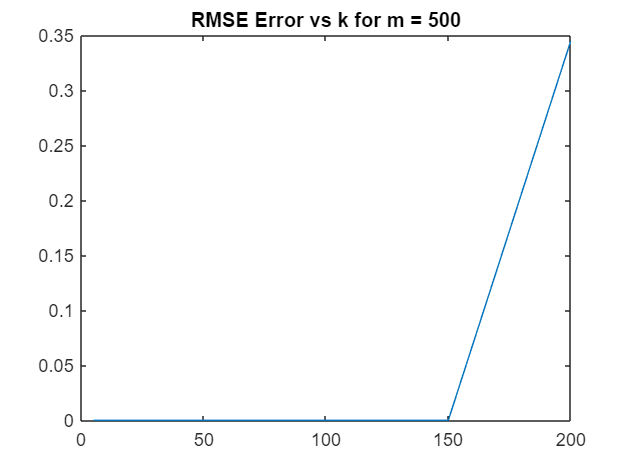

plot(K, IHTA_500);
title("RMSE Error vs k for m = 500");

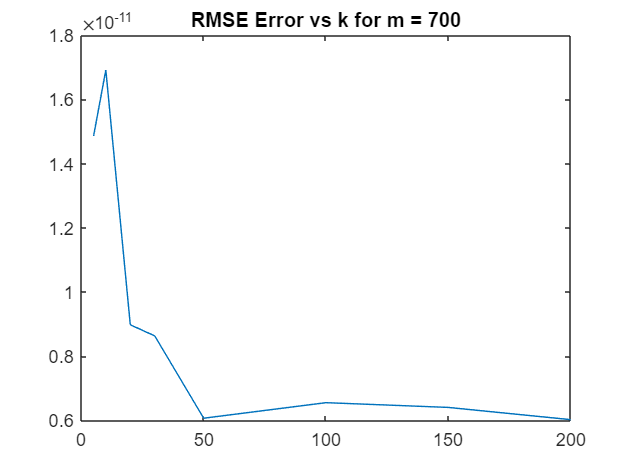

figure;
plot(K, IHTA_700);
title("RMSE Error vs k for m = 700");

figure;